# **SiSy Chapter 1 Introduction**

## Question 1-2

How can you mathematically describe a periodic sine signal y(t) with period of 0.5 seconds, an amplitude within the range [-2 ; 2], and by t=0 (initial condition) of y(0)=2 ?

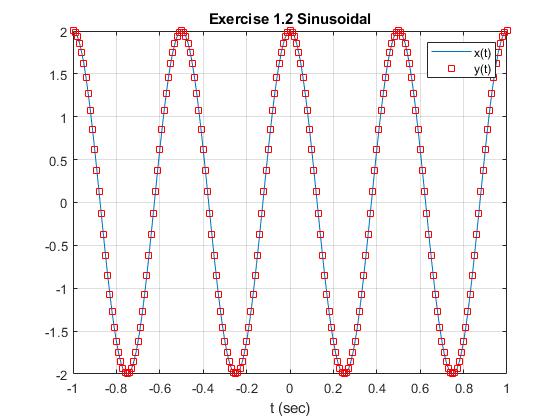

% fresh start!
clear all, close all;

% Definitions
t = -1:1e-2:1;
x_t = 2*sin(2*pi*2*t +pi/2);
y_t = 2*cos(2*pi*2*t);

% Plots
figure(1), plot(t,x_t), grid on, hold on
           plot(t,y_t,'rs'), hold off
           title('Exercise 1.2 Sinusoidal')
           xlabel('t (sec)')
           legend({'x(t)' 'y(t)'})

## **Question 1-4**

The signal you described in Question 1-2, is it an odd or an even signal? Can you change its symmetry property by varying the phase of the sinusoidal function?

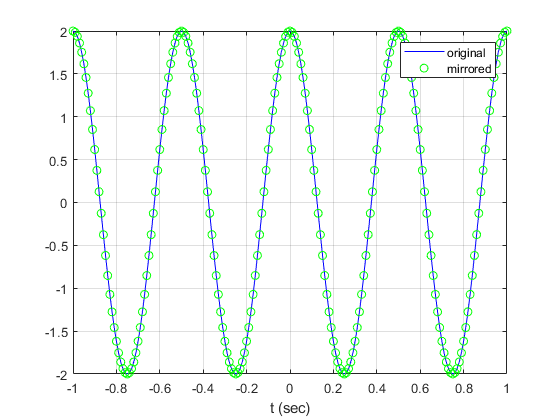

% define a mirrored function to check symmetry
y_t_mirror = 2*cos(2*pi*(-t)/0.5);

% Plots
figure(1)
plot(t,y_t,'b',t,y_t_mirror,'go'), grid on
xlabel('t (sec)')
legend({'original' 'mirrored'})

## **Question 1-8**

Use the definition of the step signal σ(t) to describe mathematically the staircase input signal from Question 1-7. 


$$x(t) = \sigma(t-0.5)+2\cdot \sigma(t-2.5)$$


% fresh start!
clear all, close all;

% Definitions
t = -1:0.05:5;

x_t = double(t>0.5) + 2*double(t>2.5);

figure(), plot(t,x_t), grid on, hold on
        ylim([min(x_t)-0.5 max(x_t)+0.5])
        title('Question 1-8 RC-System In/Out')
        xlabel('\rightarrow t')
        

## **Question 1-9**

Use the information of Figure 1-4 to define the step response of the passive RC circuit. Can you imagine a mathematical function that describes this step response? 

*Solution: The function in figure 1-4, looks like a step minus a decaying exponential.*

*We will learn later in chapter 5 that it is indeed, for a step input σ(t) , the corresponding output (called step response): *

                    $y_{step} (t) = 1-e^\frac{-t}{\tau}
$*        with         *$\tau = R \cdot C$

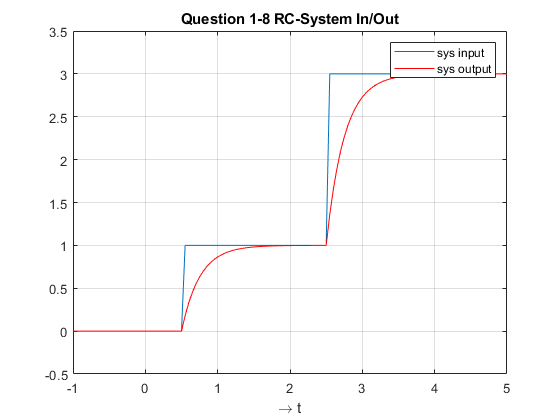

tau = 0.25;
term_1 = 1*(1-exp(-(t-0.5)/tau)).*double(t>0.5) ;
term_2 = 2*(1-exp(-(t-2.5)/tau)).*double(t>2.5) ;

y_t = term_1 + term_2; 

plot(t,y_t,'r'), hold off
    legend({'sys input' 'sys output'})

## **Question 1-10**

Calculate the following integral and compare the result to the step function. 

What is the relationship between the step and the impulse functions? 

                                   
$$y(t) = \int _{-\infty} ^{t} {\delta (\lambda)} d\lambda = \sigma(t)$$
                   

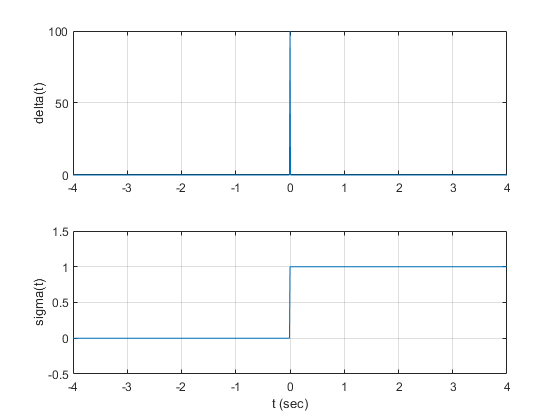

% fresh start!
clear all, close all;

% Definitions
tstep = 1e-2;
t = -4:tstep:4;

del_t = (1/tstep)*double(t==0);
sig_t = tstep*cumsum(del_t);

figure()
subplot(211),plot(t,del_t), grid on, ylabel('delta(t)')
subplot(212),plot(t,sig_t), grid on, ylabel('sigma(t)')
       ylim([-0.5 1.5]), xlabel('t (sec)')               

## Question 1-11

*Draw a graphic representing the function x(t) with respect to time, and a second graphic representing x(t) as a sum of phasors in a complex plane.  *

  
$$x(t) = cos(8\pi t + \frac{\pi}{4} )$$


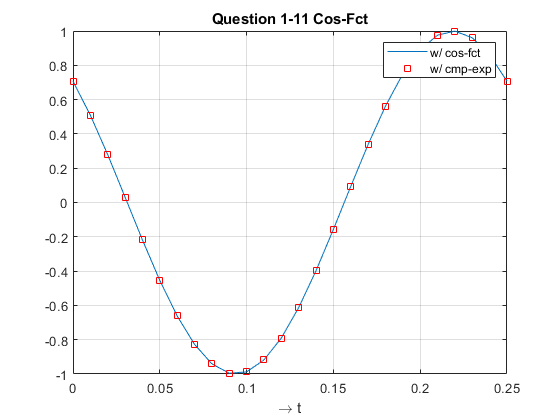

clear all, close all;

% define a time vector
t = 0:1e-2:0.25;
x_t = cos(8*pi*t+pi/4);
y_t = 0.5* (exp(j*(8*pi*t+pi/4)) + exp(-j*(8*pi*t+pi/4)) );

% plot function
figure(1), plot(t,x_t), grid on, hold on;
           plot(t,y_t,'rs'),hold off,  
    title('Question 1-11 Cos-Fct')
    xlabel('\rightarrow t')
    legend({'w/ cos-fct','w/ cmp-exp'}) 

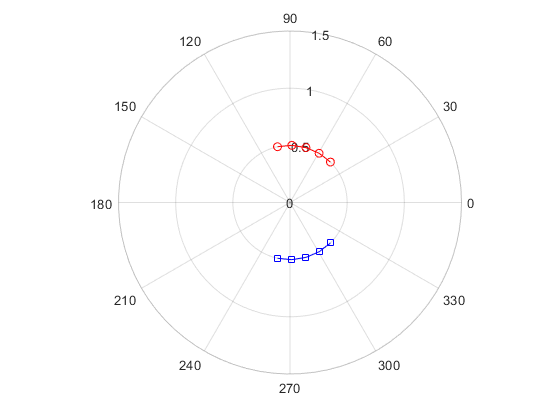

    
    
% plot now some pairs of phasors using
% polar(THETA, RHO)
theta1 =   8*pi*t+pi/4 ; 
theta2 = -(8*pi*t+pi/4) ; 
rho = 0.5*ones(1,length(t));

figure(2), polarplot(theta1(1:5),rho(1:5),'r-o'),hold on,grid on,
           polarplot(theta2(1:5),rho(1:5),'b-s'),hold off

## Question 1-12

Define the equation that describes the function y(t) represented in the graphics below:

Solution :     $y(t) = -3  \cdot cos(10\pi t) $

check with a plot...

%  Here you can type your code! (:o) 



## Question 1-13

Solution :     $u(t) = cos(\frac{\pi}{2} t) =
0.5 \cdot \left[ exp(j\frac{\pi}{2} t) +
                      exp(-j\frac{\pi}{2} t) \right]$

check with a plot...

%  Here you can type your code! (:o) 



## Question 1-14

Given $x\left(t\right)=\mathrm{cos}\left(2\pi \;f_{\mathrm{sig}\;} t+\phi_0 \right)\;$x(t)  generate a plot in Matlab of the corresponding discrete function x[n], using the following numerical values:

- 
$$f_{\mathrm{sig}\;} =1\mathrm{kHz}$$


- 
$$\phi_0 =-\frac{\;\pi \;}{6}$$


- $F_{s\;} =20\mathrm{kHz}$�

Determine the value of the normalised angular frequency Ω [radians/sample]

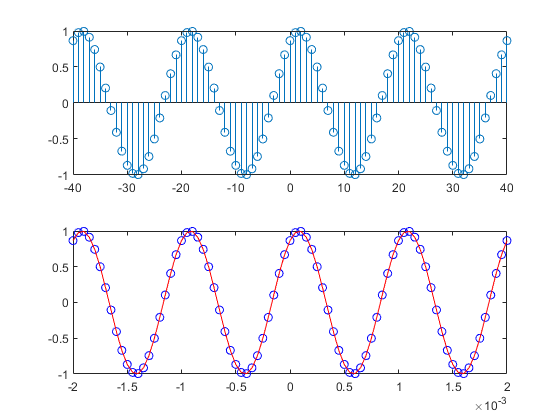

clear all, close all, clc

% Parameters
fsig = 1e3;
phi0 = -pi/6;
Fs = 20e3;

Omega = pi/10;          % 2*pi*fsig/Fs
M = Fs/fsig ;           % number of points per period = Tsig/Ts
nvec  = -2*M:1:2*M;     % to visualise 4 periods

x_n = cos(Omega*nvec + phi0);

% can compare with
tvec = (1/Fs)* nvec; 
x_t = cos(2*pi*fsig*tvec + phi0);

figure()
subplot(211),stem(nvec,x_n)
subplot(212),plot(tvec,x_n,'bo',tvec,x_t,'r-')

## Question 1-15 : Correlation-Example with sinus + noise

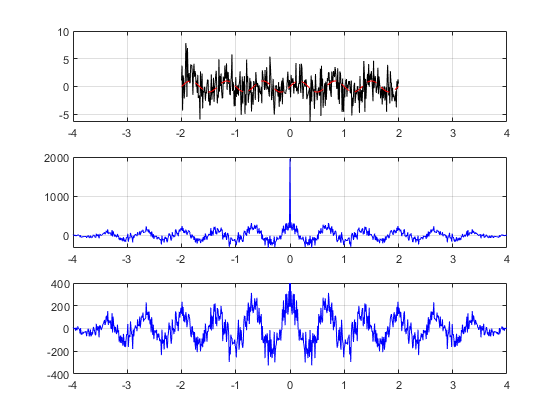

clear all,close all, clc

% TIME VECTOR & FUNCTIONS
tstep = 1e-2;
Vmax = 2;
t = -Vmax:tstep:+Vmax;
t_long = -2*Vmax:tstep:+2*Vmax;     % longer time vector to plot auto-correlation 

s_t = 1*sin(2*pi*1.5*t);            % signal
n_t = 2*randn(1,length(s_t));       % noise vector with std-dev=2 & same length as signal
spn_t =  s_t + n_t;                 % signal+noise
Acor = xcorr(spn_t);                % autocorrelation of signal+noise

% PLOTS
figure(1),
subplot(311),plot(t,spn_t,'k',t,s_t,'r--'), grid on
% subplot(311),plot(t,spn_t,'k'), grid on
            xlim([t_long(1) t_long(end)])
subplot(312),plot(t_long,Acor,'b'),grid on            
subplot(313),plot(t_long,Acor,'b'),grid on
            ylim([-400 400])

## Convolution-Example

(from Pre-SiSy Math List exercise-13 )

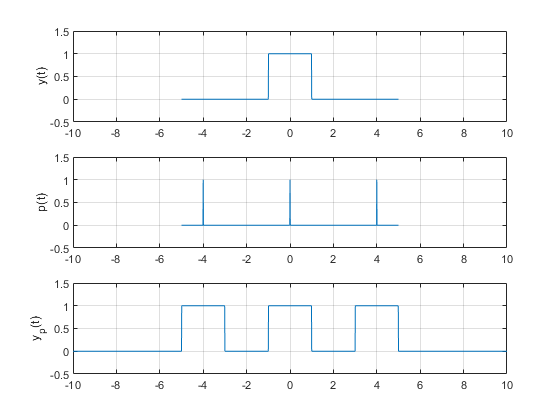

clear all, close all

tstep = 1e-2;
t = -5:tstep:5;
t_long = -10:tstep:10;

y_t = double( abs(t)<1 );
p_t = double( (t==-4) | (t==0) | (t==4) );
yp_t = conv(y_t,p_t);

subplot(311), plot (t,y_t),grid on, ylim([-0.5 1.5]), xlim([-10 10]), ylabel('y(t)')
subplot(312), plot (t,p_t),grid on, ylim([-0.5 1.5]), xlim([-10 10]), ylabel('p(t)')
subplot(313), plot (t_long,yp_t),grid on, ylim([-0.5 1.5]), xlim([-10 10]), ylabel('y_p(t)')